Name: Saikrishna Saketh Y

Student Number: 723400

**A quick report**

- BER is observed to be 0 for 50% of the Simulation

- Selection Parameters of Fo, Fb, and Fs are chosen according to the underlying instructions, I chose Fo, which is strictly less than 15Khz

- Fb is chosen in such a manner that cycles/bit is an integer

Fs is the Sampling frequency chosen based on Nyquist Criterion

FOn-off keying using FM transmitting and RTL-SDR

By R.W.

clear all, close all

% addpath ../funcs
% ==================================================================
%Script to set parameters
%rw_fmrx_init

% File to dump the output signal
fnam = 'ook_signal.wav';

% Parameters to choose:
%
% Frequency indicating bit one. Should be below 15KHz
% Choose Fc and Fs such that the sinusoid makes one or more full cycles so
% that there is no discontinuity between successive 1 bits.
Fo = 14e3;% < 15KHz
% Frequency of the information bits to send. Fo/Fb is then the number of
% cycles/bit.
Fb = 2e3; % EVery bit has 3 cycles
% % Sampling rate of the FM modulator's input signal. 
% Note that the FM bandwidth is 15 KHz
Fs = 140e3;
% Fs/Fo samples in one cycle of the sine wave. This should be around 10
% to produce a smooth sine wave
%
% Implement OOK modulation rw_ook_modulation (one line)
% Implement FM demodulator rw_fmrx
% Implement envelope detector and down-sampling rw_comb_env (3 lines)
% Implement matched filter rw_matched_filter (one line)

% Typically the overhead from control signaling in wireless sytems is 10-20%
% Here preamble is the only control signal (no channel estimation, power
% control command, system information...) so the overhead can be smaller.
% It's arbitrary in this exercise anyway.
% #Information bits/message
Nbit = 300-13;
% Sets ;the seed for the random generator so that the message is always the
% same
rng(2308975234);
% Message consists of zeros and ones
msg = randn(1,Nbit) > 0;
% Preamble: Barker sequence in binary form
b13 =  [1 1 1 1 1 0 0 1 1 0 1 0 1];
% A slot consists of the header and the payload
slot = [b13,msg]; 
% A frame consists of Nslot slots
Nslot = 8;
frame = kron(ones(1,Nslot), slot);
% Make msg a column vector for the compatibility of dimensions
msg = msg(:);

% front-end sampling rate, 
FESR = 240e3;
% Read two slots at a time. This way there is at least one
% complete slot in one vector read by the dongle
Nsample = 2*FESR/Fb*length(slot);
% #Output vectors to read from the dongle
Nloop = 100;

% ===========================================================================

## Part 1: Make the signal to transmit

Make a wav file that is then used as input to FM transmitter OOK odulation, no pulse shaping. Sine wave signals bit 1 Information signal for FM modulation at sampling frequency Fs

ook_signal = rw_ook_modulation(frame,Fs,Fb,Fo);

%This would be the FM modulation in Matlab without over-the
% air transmission (without the carrier)
%beta=1;
%theta = beta*cumsum([0,si]);
% Time axes
%t = [0: 1/Fs: (length(theta)-1)/Fs];

## Write the frame into audio file

This file is then transmitted with the FM transmitter Dongle has 8-bit analog-to-digital converter, so use the same number here audiowrite(fnam,ook_signal,Fs,'BitsPerSample',8,... 'Title','OOK signal','Artist','RW','Comment',date)

audiowrite(fnam,[ook_signal ook_signal ook_signal ook_signal ook_signal ook_signal ook_signal ook_signal ook_signal] ,Fs,'BitsPerSample',8,...
	'Title','OOK signal','Artist','RW','Comment',date)
audioinfo(fnam)

ans = struct with fields:
             Filename: 'F:\Aalto\Course_Work_&_Modules\Period I-II 2018\Signal_Processing_for_Comm\Code\E5410-master\matlab\task10\ook_signal.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 140000
         TotalSamples: 1512000
             Duration: 10.8000
                Title: 'OOK signal'
              Comment: '06-Dec-2018'
               Artist: 'RW'
        BitsPerSample: 8



% The way to run audio in Ubuntu with Alsa 
%system('speaker-test -r sampling-rate -l 0 -t wav -W . -w fm_data.wav')
% 
% In /bin/bash
% while :; do afplay -r sampling-rate fm_data.wav; done
%
% Quicktime in Mac, Mediaplayer in Windows
% In Windows we play
%powershell -c (New-Object Media.SoundPlayer "c:\PathTo\YourSound.wav").PlaySync();
%
% Or upload to a phone and transmit
%
% Put your system to transmit until you move on to the receiver part


% ============================================================================

## Part 2: Receive

Radio parameters. Find an empty channel without any FM station

expFreq = 89.5e6;

hSDRrRx = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency',     expFreq, ...
    'EnableTunerAGC',      true, ...
    'SampleRate',          FESR, ...
    'SamplesPerFrame',     Nsample, ...
    'FrequencyCorrection', 60, ...
    'OutputDataType',      'double');

hSpectrumAnalyzer = dsp.SpectrumAnalyzer(...
    'Name',             'Actual Frequency Offset',...
    'Title',            'Actual Frequency Offset', ...
    'SpectrumType',     'Power density',...
    'FrequencySpan',    'Full', ...
    'SampleRate',       FESR, ...
    'YLimits',          [-60,10],...
    'SpectralAverages', 10, ...
    'FrequencySpan',    'Start and stop frequencies', ...
    'StartFrequency',   -50e3, ...
    'StopFrequency',    50e3,...
    'Position',         figposition([50 30 30 40]));

## Rx loop

Time elapsed

fprintf('Loop time: %f s\n',Nsample*Nloop/FESR)

Loop time: 30.000000 s


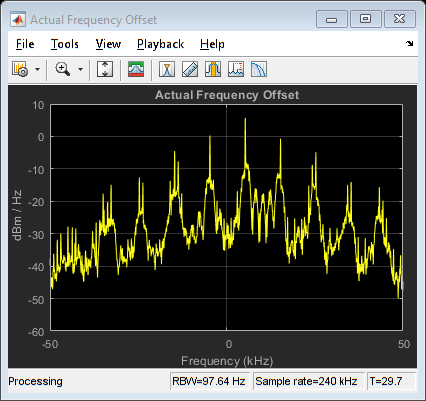

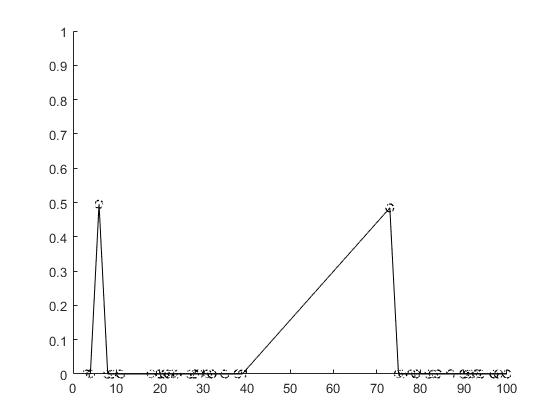

Elapsed time 32.546786 s


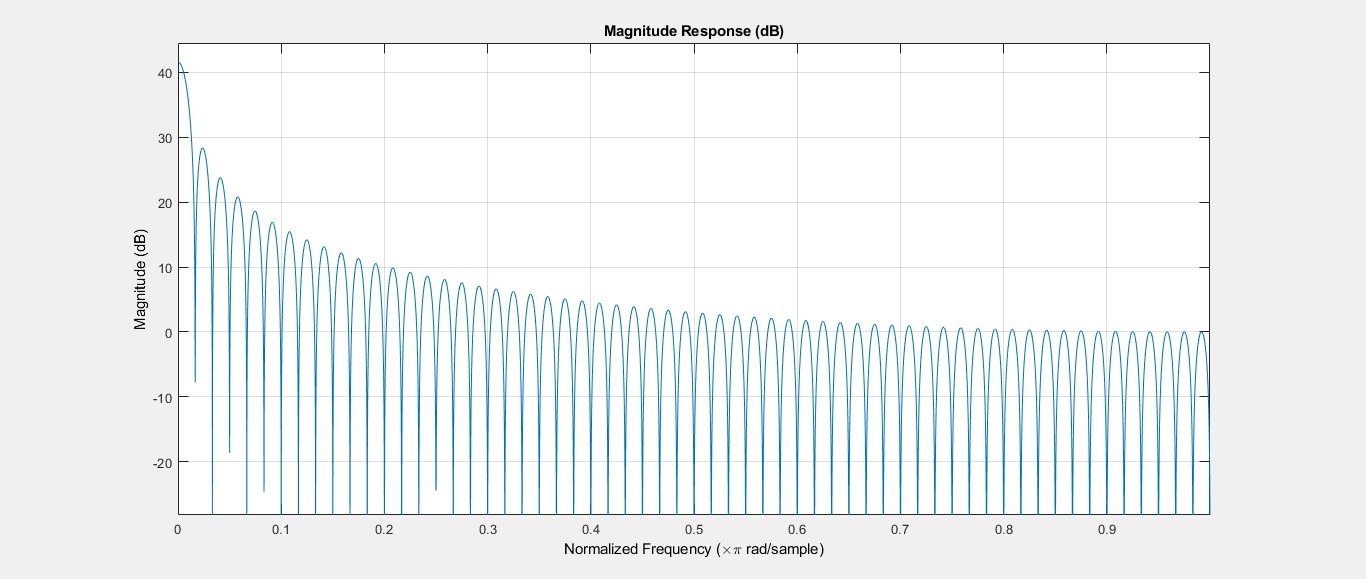

% Allocate memory for signal storage
%rxSigStore = zeros(1,Nsample*Nloop);
if ~isempty(sdrinfo(hSDRrRx.RadioAddress))
    ber_vec = ones(1,Nloop);
    fb = figure('Name', 'BER');
    hb = animatedline('Marker','o');
    axis([0 Nloop 0 1]);
    
    tstart = tic;
    for ii = 1:Nloop
        [rxSig, ~] = step(hSDRrRx); 
        rxSig = rxSig - mean(rxSig);  % Remove DC component
        
        % Display received frequency spectrum
        hSpectrumAnalyzer(rxSig);
  
		%rxSigStore((iFrame-1)*SPF+[1:SPF]) = rxSig;
        % FM demodulator using discriminator
        rd = rw_fmrx(rxSig,1);
 
        % Envelope detection and down-sampling
        % FESR/fb = total down-sampling factor, Ncic = length of the
        % corresponding moving average filter
        Ncic =1;
        ds = FESR/Fb;
        soft_symbols = rw_env_comb(rd,ds);
        
        % Subtract the mean in order to do sign detection 
        soft_symbols = soft_symbols - mean(soft_symbols);
 
        % Matched filter to the preamble sequence
        after_mf = rw_matched_filter(soft_symbols);
        % Find the preamble i.e.  index of the max. peak
        [~,idx] = max(after_mf);
        % If the index is too large so that the slot cannot start here,
        % don't attempt to decode and go read a new sample vector
        if idx+Nbit > 2*Nbit
            continue
        end
        % Index OK, decode
        msgd = soft_symbols(idx+[1:Nbit]) >0;
        
        % Bit-error rate
        ber_vec(ii) = sum(xor(msg,msgd))/Nbit;
        %fprintf('Bit error rate %f at round %d\n', ber_vec(ii), ii)
        % Plot BER point by point. Comment out if too slow
        addpoints(hb, ii, ber_vec(ii)), drawnow limitrate
	end
    fprintf('Elapsed time %f s\n', toc(tstart))
    %
    %Depict the magnitude response of the cascaded integrator comb filter
    fvtool([1 zeros(1,ds-1)/ds -1],[1 -1]);
    % Check the bit-error rates
    %stem(ber_vec)
else
    warning(message('SDR:sysobjdemos:MainLoop'))
end

## Release all System objects

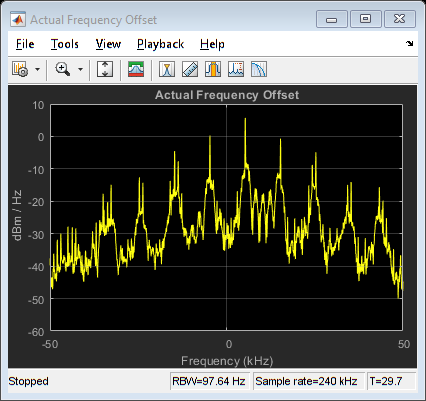

release(hSDRrRx); 
release(hSpectrumAnalyzer)

clear hSDRrRx

## Functions Required

%1

function ook_signal = rw_ook_modulation(frame,Fs,Fb,Fo)
    samples_per_bit = Fs/Fb;
    bits = size(frame,2);
    time = 0:1/Fs : (samples_per_bit*bits-1)/Fs; %Total Length and from time axes hint above
    signal = sin(2*pi*Fo*time); %sin(2*pi*F*T)
    ook_signal = signal.*repelem(frame,samples_per_bit); %using repeat elements
end
%2
function rd = rw_fmrx(rxSig,delay)
    filterdelay = filter([zeros(1,delay) 1],1,rxSig);
    rd = angle(filterdelay .* conj(rxSig));
    FLOW = fir2(48, [0 15e3/(240e3/2) 17e3/(240e3/2) 1], [1 1 0 0]);
    memo = zeros(1,length(FLOW)-1);
    [rd,~] = filter(FLOW,1,rd,memo);
end
%3
function ss = rw_env_comb(rd,ds)

rectified = abs(rd);
%ds = FESR/Fb;
ss= filter([1 zeros(1,ds-1)/ds -1],[1 -1],abs(rectified));
ss = ss(1:ds:end);
end
%4
%Ask Mikko on Friday
function after_mf = rw_matched_filter(soft_symbols)
    after_mf = filter(fliplr([1 1 1 1 1 -1 -1 1 1 -1 1 -1 1]),1,soft_symbols);
end